# Not In My Backyard (NIMBY)

This program demonstrates random waypoint mobility with obstacle avoidance logic integrated. During this demo, the drone will attempt to avoid entering or path planning through a restricted zone. If it does enter one, it will navigate to the nearest boundary and exit the area. The program was written by Josh Josey with help and code snippets from examples within the UAV toolbox documentation.

### **Define the simulation variables**

Px = 6; Py = 6; Pz = 6.5;       %Proportional Coeffecients
Dx = 1.5; Dy = 1.5; Dz = 2.5;   %Derivative Coeffecients
Ix = 0; Iy = 0; Iz = 0;         %Integral Coeffecients
Nx = 10; Ny = 10; Nz = 14.4947065605712; %Filter Coefficients
escapeMargin = 1;
Gravity = 9.81;
DroneMass = 0.1;
UAVSampleTime = 0.01;
runtime = 100;

### Create a UAV scenario & platform

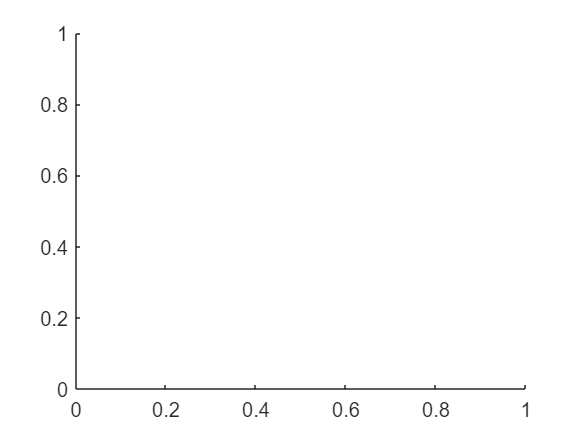

hold off

Scenario = uavScenario("UpdateRate",100,"ReferenceLocation",[0 0 0]);
%mark the starting location
InitialPosition = [0 0 0];
InitialOrientation = [0 0 0];
InitialWPS = [InitialPosition; 0 0 -10];
addMesh(Scenario,"cylinder",{[InitialPosition(2) InitialPosition(1) 1] [0 .01]},[0 1 1]);  

%create a UAV model in the scenario
platUAV = uavPlatform("UAV",Scenario, ...
                    "ReferenceFrame","ENU", ...
                    "InitialPosition",InitialPosition, ...
                    "InitialOrientation",eul2quat(InitialOrientation));

%add the drone mesh over the model (style,size,color,orientation)
updateMesh(platUAV,"quadrotor",{1},[1 0 1],eul2tform([0 0 pi]));

### Add in obstacles

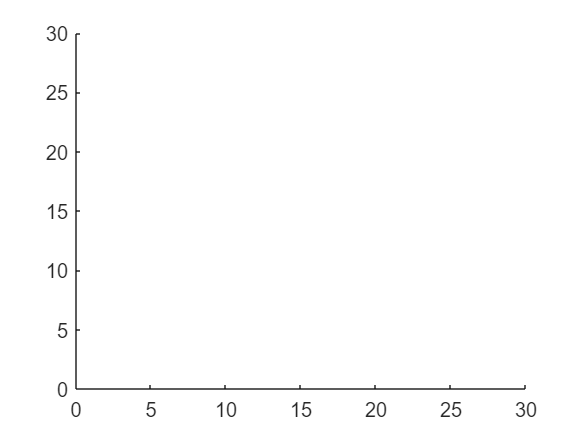

%Obstacle locations & dimensions
obstaclePos = [5 5 0;5 25 0; 25 25 0; 25 5 0; 15 15 0];
obstacleHeight = 15;
obstacleWidth = 5;

%create an obstacle struct for passing to functions
obs.Pos = obstaclePos;
obs.Height = obstacleHeight;
obs.Width = obstacleWidth;

%plot the obstacles
for i = 1:size(obstaclePos,1)
    addMesh(Scenario, "polygon", ...
            {  %the sides of the obstacle
               [obstaclePos(i,1)-obstacleWidth/2 obstaclePos(i,2)-obstacleWidth/2;
                obstaclePos(i,1)+obstacleWidth/2 obstaclePos(i,2)-obstacleWidth/2;
                obstaclePos(i,1)+obstacleWidth/2 obstaclePos(i,2)+obstacleWidth/2;
                obstaclePos(i,1)-obstacleWidth/2 obstaclePos(i,2)+obstacleWidth/2;],
               %the height of the obstacle
               [obstaclePos(i,3) obstaclePos(i,3)+obstacleHeight]
            },[1 .3 0]);
end

xlim([0 30]);  
ylim([0 30]);

### Run the simulation and extract data

out = sim("NIMBY.slx");

%extract the drones trajectory
points = squeeze(out.trajectoryPoints(1,:,:))';

%extract the waypoints
Waypoints = squeeze(out.waypoints)';
%Waypoints = unique(Waypoints, 'rows','stable');
Waypoints = [Waypoints(1,:);Waypoints(end,:)]

Waypoints =      0     0   -10
     0     0   -10


### Plot the waypoints & trajectory

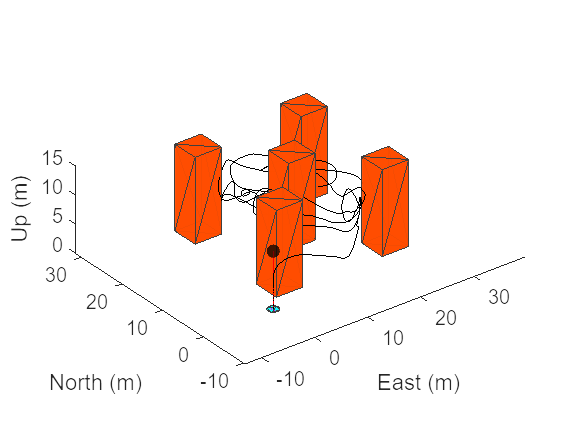

clf;
hold on;
[X,Y,Z] = sphere;
%plot the first waypoint in cyan
surf(X+Waypoints(1,2), Y+Waypoints(1,1), Z-Waypoints(1,3),'FaceAlpha',0.5,'EdgeColor','none','FaceColor','black')
for i = 2:size(Waypoints,1)-1
    %To view the waypoints DURING the flight sim, uncomment
    %addMesh(Scenario,"cylinder",{[Waypoints(i,2) Waypoints(i,1) 1] [0 0.1]},[0 .8 .3]);
    surf(X+Waypoints(i,2), Y+Waypoints(i,1), Z-Waypoints(i,3),'FaceAlpha',0.5,'EdgeColor','none')
end
%plot the final waypoint in black
surf(X+Waypoints(end,2), Y+Waypoints(end,1), Z-Waypoints(end,3),'FaceAlpha',0.5,'EdgeColor','none','FaceColor','black')

%plot the straight line path between points
plot3([InitialPosition(1,2); Waypoints(:,2)],[InitialPosition(1,2); Waypoints(:,1)],[-InitialPosition(1,3); -Waypoints(:,3)],"-r");

%plot the trajectory (BLACK)
plot3(points(:,2),points(:,1),-points(:,3),"-k");

show3D(Scenario);

### Simulation Report

disp("Simulation Report ---")

Simulation Report ---


str = 'Total Time: '; value = out.tout(end); fprintf('%s %.3f\n', str, value);

Total Time:  100.000



slDist = 0;
for i = 1:size(Waypoints)-1
        slDist = slDist + sqrt(sum((Waypoints(i+1, :) - Waypoints(i, :)).^2));
end
str = 'Straight Line Distance: '; value = slDist; fprintf('%s %.3f\n', str, value);

Straight Line Distance:  0.000



ptts = out.trajectoryPoints(:,:,:);
dist = 0;
for i = 1:size(ptts(:,:,:),3)-1
    dist = dist + sqrt(sum((ptts(:,:,i+1, :) - ptts(:,:,i, :)).^2));
end
str = 'Total Distance: '; value = dist; fprintf('%s %.3f\n', str, value);

Total Distance:  306.661



str = 'Number of waypoints: '; value = size(Waypoints); fprintf('%s %d\n', str, value);

Number of waypoints:  2
□ 